# `Model Lotki-Volterry`

`Hubert Jackowski`

`Ustalamy zmienne wymagane do symulacji wzamejmnej zależności rozmiarów populacji drapieżników i ofiar.`

time = 20;
dt = 0.0001;
n = time / dt;
prey = linspace(2, 2, n);
predators = linspace(1, 1, n);

`Ustalamy parametry opisujące model.`

a = 1.2; b = 0.6; c = 0.3; d = 0.8;

`Symulacja zmian obu populacji.`

for i=2:1:n
    tempPrey = prey(i-1);
    tempPredators = predators(i-1);
    prey(i) = tempPrey + (a - b * tempPredators) * tempPrey * dt;
    predators(i) = tempPredators + (c * tempPrey - d) * tempPredators * dt;
end

`Utworzenie wykresu zmiany populacji drapieżników i ofiar w czasie.`

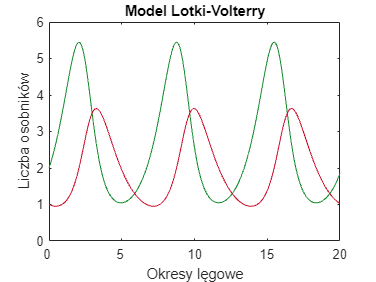

plot(prey, color="#138a2b")
hold on
plot(predators, color="#cc0e2b")
set(gca, 'XTick', 0:5/dt:n, 'XTickLabel', 0:5:time)
title('Model Lotki-Volterry') 
ylabel('Liczba osobników') 
xlabel('Okresy lęgowe')

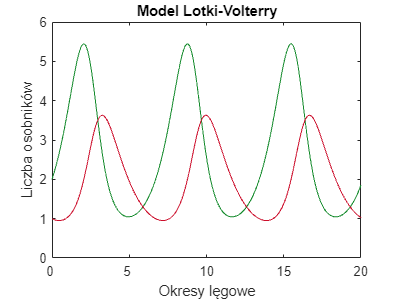

`Figure 1: Rezultat symulacji kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

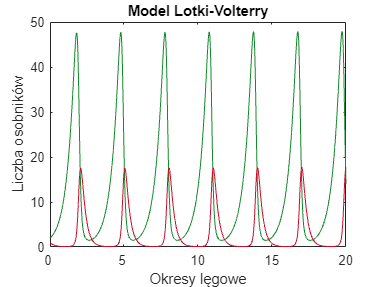

`Figure 2: Rezultat symulacji dla zmienionych wartości parametrów modelu (a = 2, b = 0.6, c = 0.3, d = 4) kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

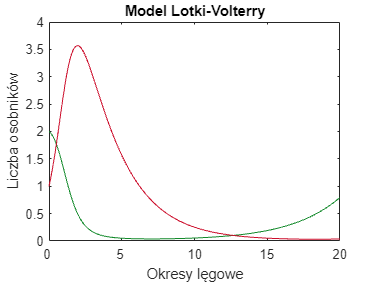

`Figure 3: Rezultat symulacji dla zmienionych wartości parametrów modelu (a = 0.3, b = 0.4, c = 0.8, d = 0.4) kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

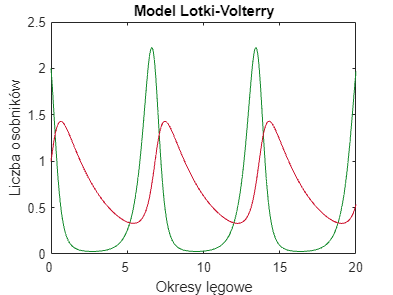

`Figure 3: Rezultat symulacji dla zmienionych wartości parametrów modelu (a = 3, b = 4, c = 0.8, d = 0.4) kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`